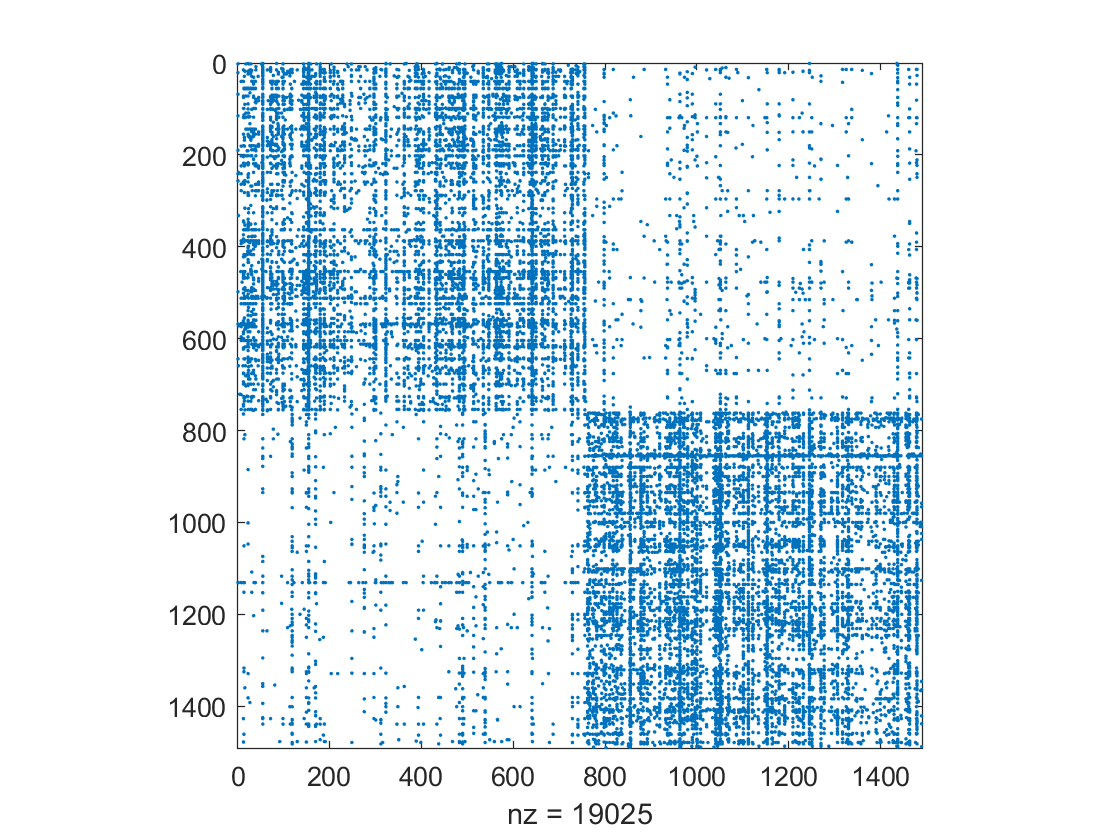

load("spectraGraphPartitioning-polblogs.mat");

A = Problem.A;
spy(A);

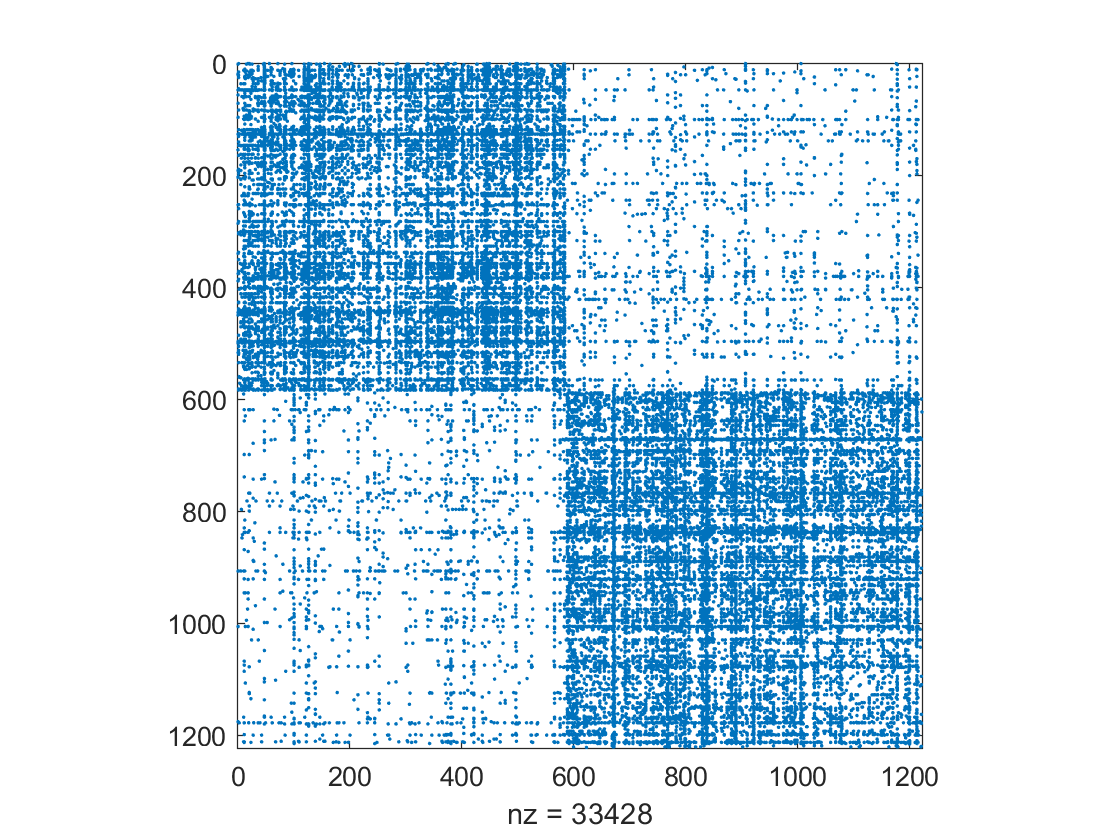

[An, ind]=normalizeA(A);
spy(An);

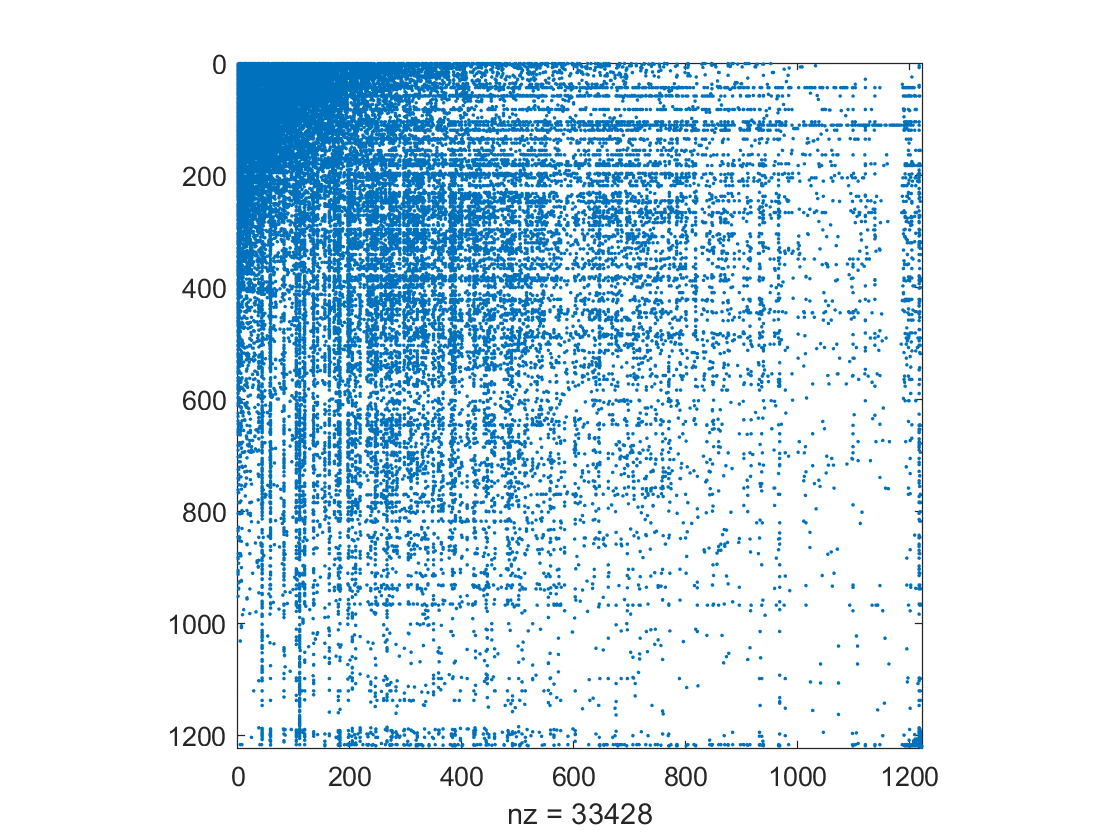

[Ln,d]=GetLaplacian(An);
Ln=normalizeL(Ln);
Fiedler=GetFiedler(Ln);
[Ap,P,p] = PermuteA(Fiedler,An);
spy(Ap);

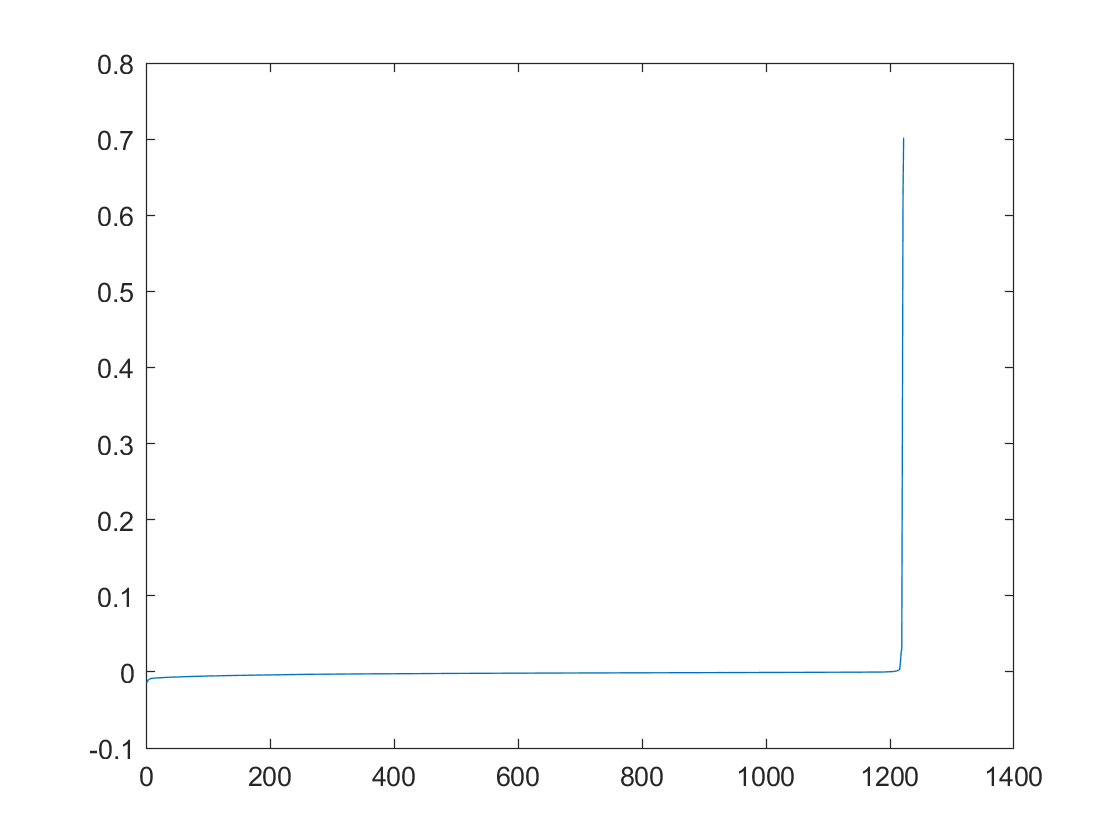

plot(Fiedler(p),'-');

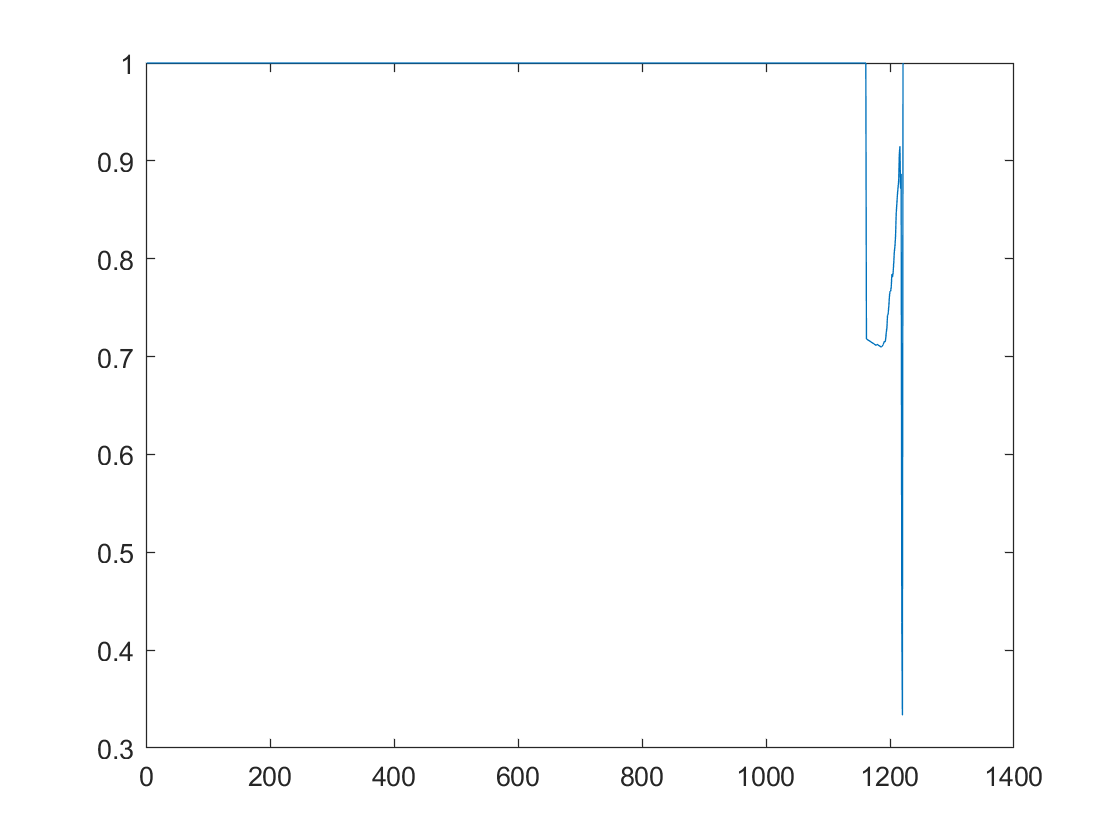

[f1,f2]=splitFiedler(Fiedler,0);
n=sum(f2);
dp = permuted(P,d);
[cond,minInd]=conductance(Ap,dp,n);
plot(cond(:,1),'-');

n=minInd

n = 1220

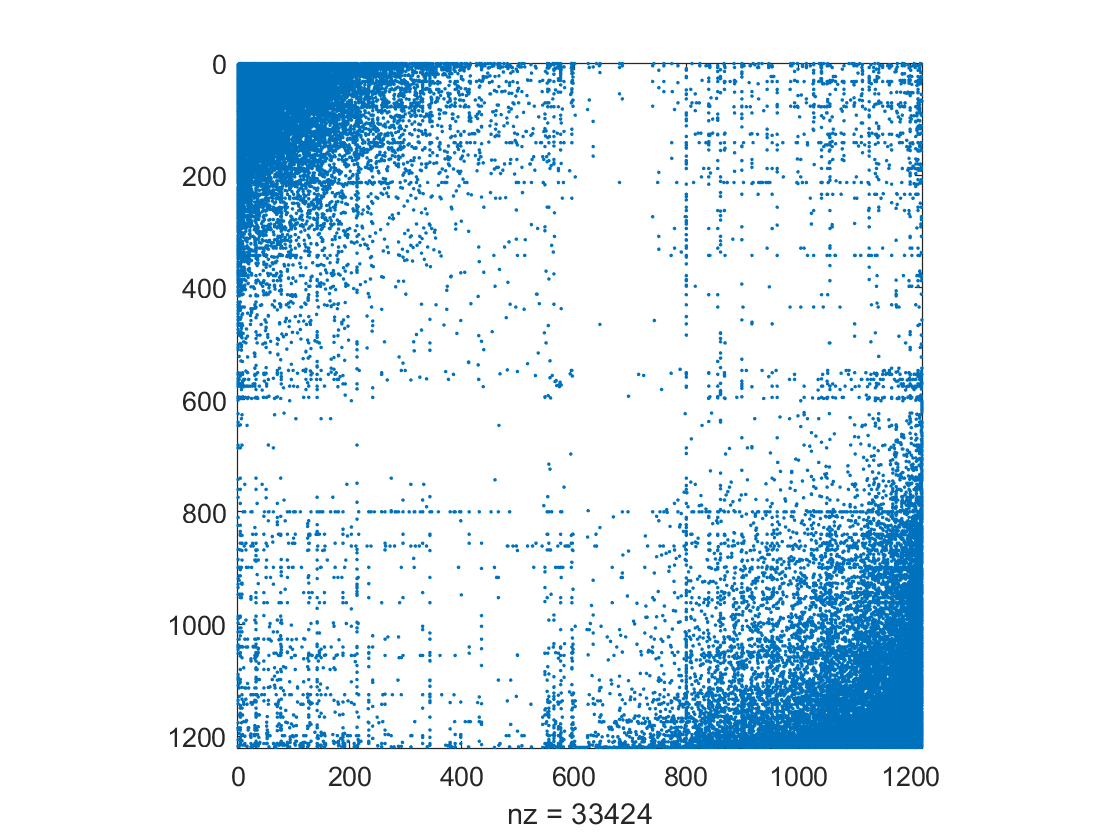

Ap2=Ap(1:n,1:n);

[Ln1,d1]=GetLaplacian(Ap2);
Ln1=normalizeL(Ln1);
Fiedler1=GetFiedler(Ln1);
[Ap1,P1,p1]=PermuteA(Fiedler1,Ap2);

spy(Ap1);

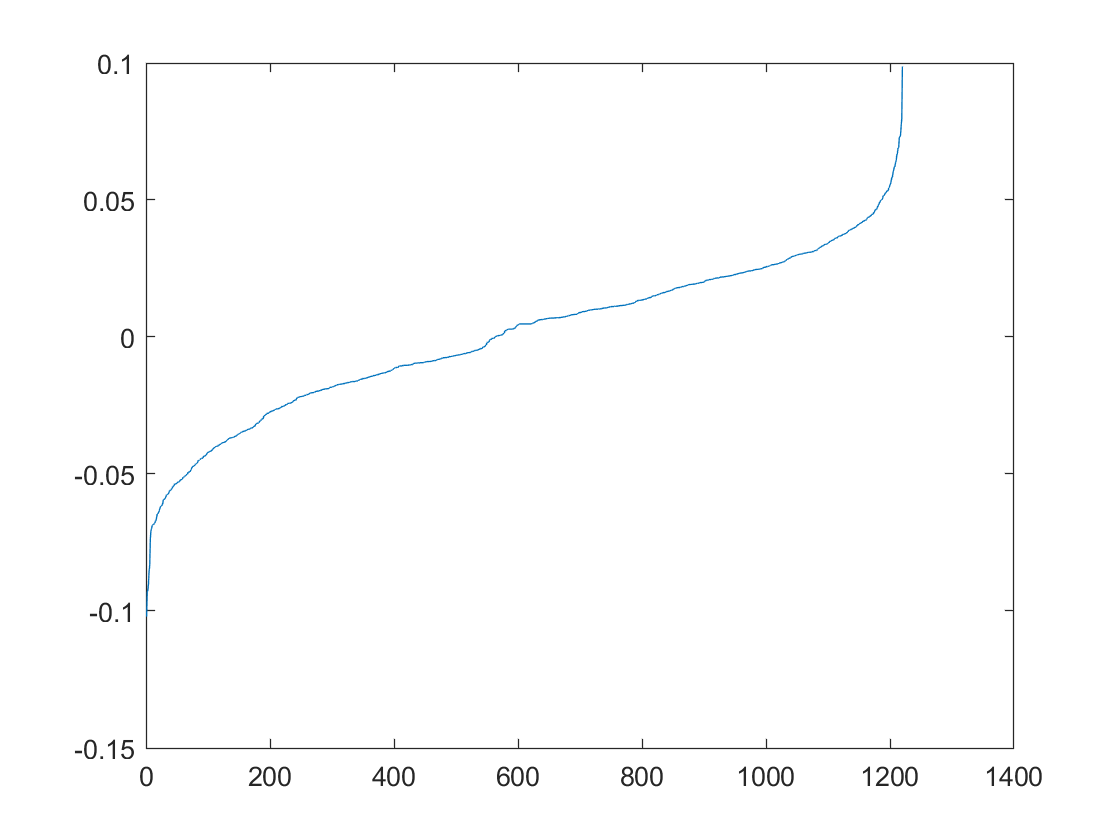


plot(Fiedler1(p1),'-');

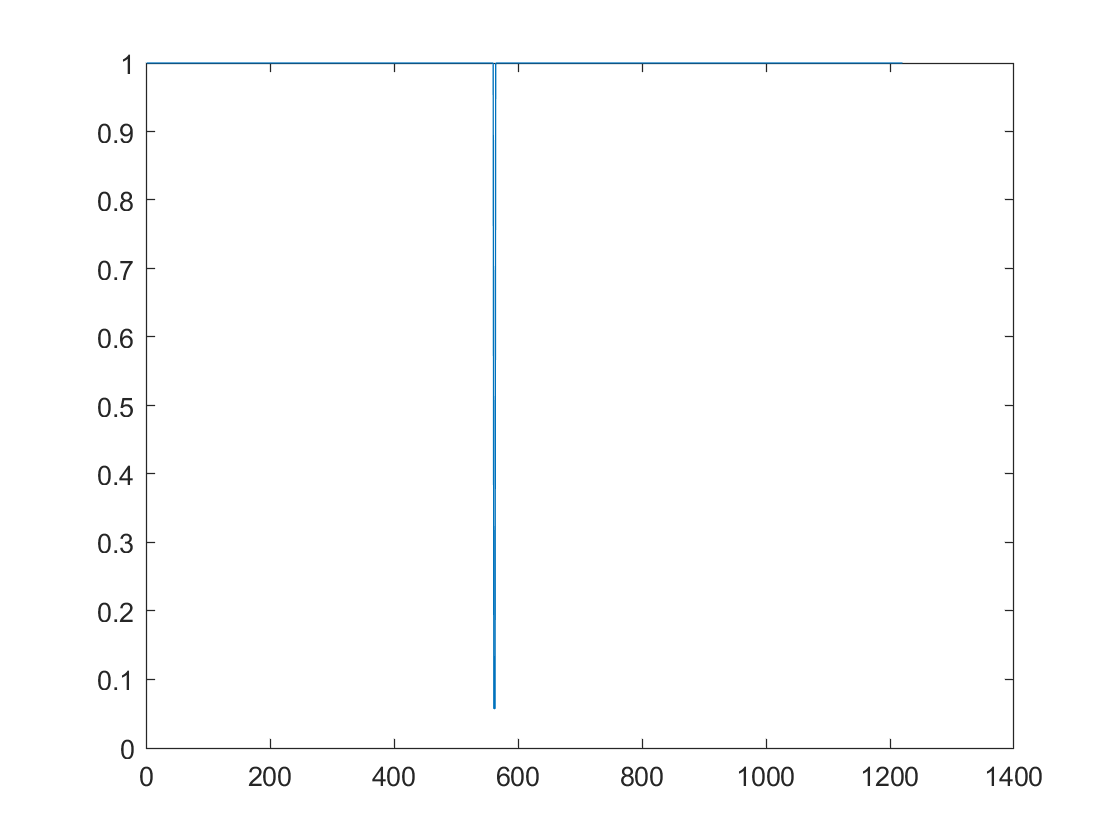


dp1 = permuted(P1,d1);

[f1,f2]=splitFiedler(Fiedler1,0);


n=sum(f2);

[cond1,minInd1]=conductance(Ap1,dp1,n);

plot(cond1(:,1),'-');


n=minInd1

n = 562

[Lmulti,~]=GetLaplacian(Ap1);
Lnmulti=normalizeL(L123);
[V,E] = eig(Lnmulti)

V123 =    -0.1095   -0.1021    0.0062   -0.0173   -0.0013   -0.0054    0.0341   -0.0064   -0.0113   -0.0017    0.0089   -0.0071   -0.0060    0.0121   -0.0010   -0.0001   -0.0072    0.0005    0.0194   -0.0131   -0.0617    0.0761   -0.0275   -0.0011   -0.0471    0.0639    0.0099   -0.0047   -0.0644   -0.0295    0.0196    0.0009   -0.0115    0.0376    0.0289   -0.0334   -0.0127   -0.0099    0.0031   -0.0195   -0.0013    0.0207   -0.0482    0.0283    0.0442   -0.0152   -0.0641    0.0107   -0.0151   -0.0582
   -0.0147   -0.0930    0.0939    0.6944    0.0008    0.0005    0.0003    0.0004    0.0018   -0.0008   -0.0007    0.0005   -0.0022    0.0027    0.0023   -0.0005    0.0010   -0.0005   -0.0000   -0.0001    0.0027    0.0019   -0.0009    0.0018   -0.0019    0.0007   -0.0000    0.0006    0.0037   -0.0002   -0.0015   -0.0001   -0.0015   -0.0015    0.0007   -0.0020    0.0003    0.0005   -0.0001   -0.0014   -0.0009    0.0003   -0.0001    0.0005    0.0010    0.0013    0.0002    0.0002    0.0003  

E123 =     0.1786         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2704         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  


k = 100;    % Number of clusters

idx = kmeans(V(:,2:k),k)

idx =      7
    82
    90
    82
    99
    90
    51
    72
    99
    90



spy(Ap1);

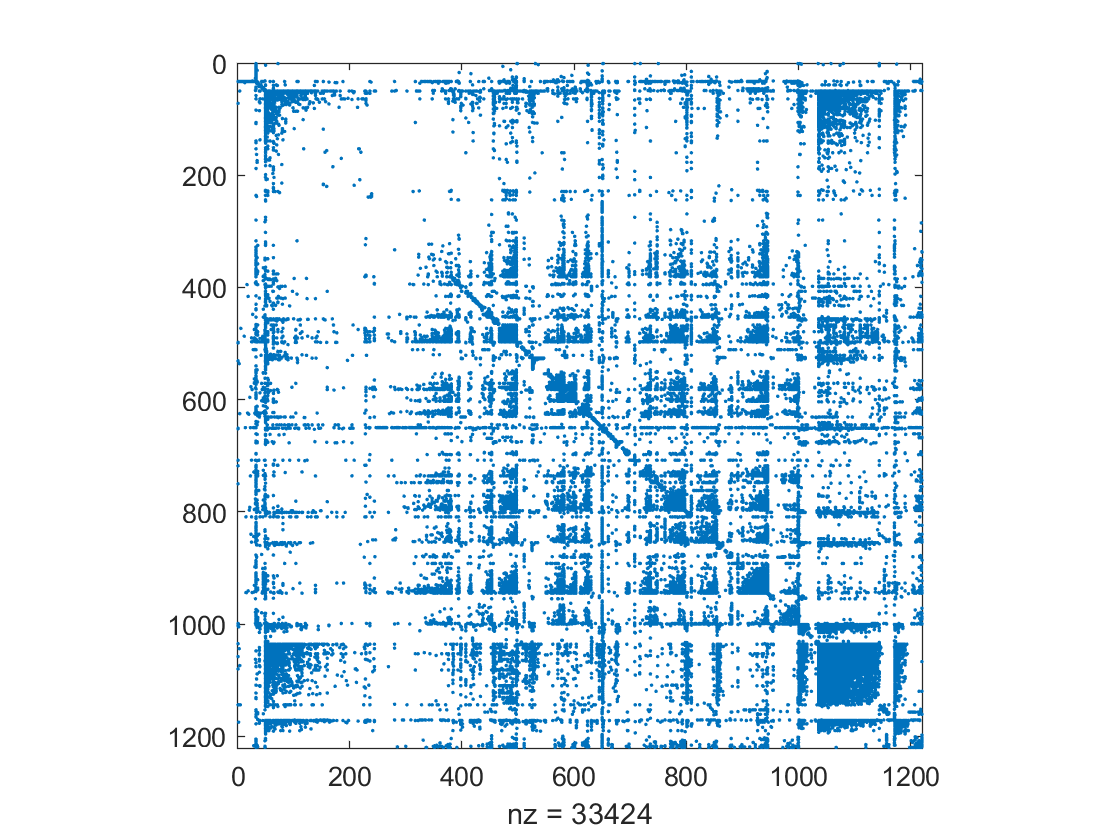


P = speye(length(idx));
[~,p] = sort(idx,'ascend');
P = P(p,:);
Amulti = P*Ap1*P';

spy(multi);